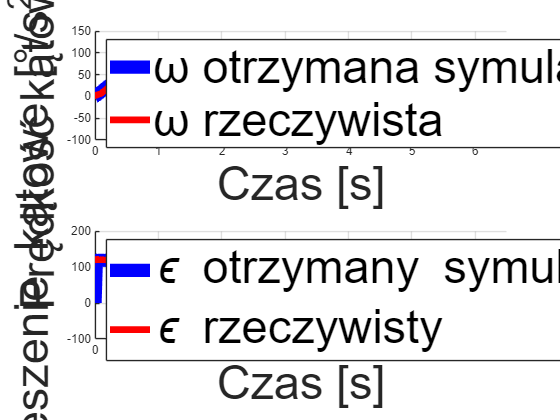

clc; clear;

ur3_RBT = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0, 0, -9.81]);

q_home = [-0, -110, -100, -60, 90, 0]*pi/180;
q_mid1 = [90, -110, -100, -60, 90, 0]*pi/180;
q_end1 = [180, -110, -100, -60, 90, 0]*pi/180;
q_mid2 = [270, -110, -100, -60, 90, 0]*pi/180;
q_end2 = [360, -110, -100, -60, 90, 0]*pi/180;

qPoints = [q_home; q_mid1; q_end1; q_mid2; q_end2];

v_max = 0.4;
a_max = 0.8;
dt = 0.01;

q_temp = jointFullArc(qPoints, 1000);
tcp_path = zeros(size(q_temp,1), 3);

for i = 1:size(q_temp,1)
    T_i = getTransform(ur3_RBT, q_temp(i,:), 'tool0', 'base');
    tcp_path(i,:) = tform2trvec(T_i);
end

tcp_dist = sum(vecnorm(diff(tcp_path), 2, 2));

t_acc = v_max / a_max;
d_acc = 0.5 * a_max * t_acc^2;

if tcp_dist < 2*d_acc
    trajTime = 2 * sqrt(tcp_dist / a_max);
else
    trajTime = 2*t_acc + (tcp_dist - 2*d_acc)/v_max;
end

N_total = round(trajTime / dt);

qArcUniform = jointFullArc(qPoints, N_total);

s = trapezoidalScaling_noDecel(trajTime, a_max, v_max, size(qArcUniform,1));

qTraj = zeros(length(s), size(qArcUniform,2));
for j = 1:size(qArcUniform,2)
    qTraj(:,j) = interp1( linspace(0,1,size(qArcUniform,1)), qArcUniform(:,j), s, 'linear');
end

qdTraj = [zeros(1,6); diff(qTraj)/dt];
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

qdTraj(end,:) = 0;
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

T = linspace(0, trajTime, size(qTraj,1));

TCP_pos = zeros(size(qTraj,1), 3);
for i = 1:size(qTraj,1)
    T_TCP = getTransform(ur3_RBT, qTraj(i,:), 'tool0', 'base');
    TCP_pos(i,:) = tform2trvec(T_TCP);
end

TCP_vel = [zeros(1,3); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

TCP_vel(end,:) = 0;
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

max_TCP_speed = max(vecnorm(TCP_vel,2,2));


M = csvread('3711_ums.csv', 1,0);

idxB = 1; idxE = length(M);

M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
subplot(2,1,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-11.32),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 6.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;

subplot(2,1,2)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-11.32,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 6.5]); ylim([-100 200]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 1132;
omega_ref = qdTraj(:,1) * 180/pi;
omega_meas = -SDLData.gZ;

omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);

omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));

fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 4.313390 [°/s]



a_ref = qddTraj(:,1) * 180/pi;
a_meas = -SDLData.aZ;

a_meas_shifted = a_meas(offset:end);

N = length(T);

a_ref = a_ref(1:N);
a_meas_shifted = a_meas_shifted(1:N);

valid_idx = (a_meas_shifted ~= 0) & (a_ref ~= 0);

a_ref_valid = a_ref(valid_idx);
a_meas_valid = a_meas_shifted(valid_idx);

if isempty(a_ref_valid)
    warning('Brak próbek spełniających warunek a_ref ≠ 0 oraz a_meas ≠ 0.');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_valid - a_meas_valid));
end

fprintf('Wartość funkcji celu I(a): %.6f [°/s^2]\n', I_acc);

Wartość funkcji celu I(a): 122.778787 [°/s^2]



I_omega_t = abs(omega_ref - omega_meas_shifted);

time_vec = T(1:N);

I_acc_t = abs(a_ref - a_meas_shifted);

I_acc_t_valid = I_acc_t;
I_acc_t_valid(~valid_idx) = NaN;

figure;
subplot(2,2,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-11.32),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 6.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,3)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-11.32,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 6.5]); ylim([-100 200]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

set(gca, 'FontSize', 35)
xlim([0 6.31]);

subplot(2,2,4)
I_acc_plot = I_acc_t_valid;
I_acc_plot(isnan(I_acc_plot)) = 0;
plot(time_vec, I_acc_plot, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
legend('Rozbieżność \epsilon', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

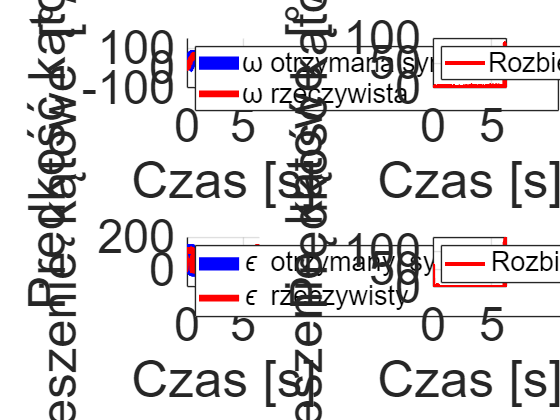

xlim([0 6.31]);
set(gca, 'FontSize', 35)

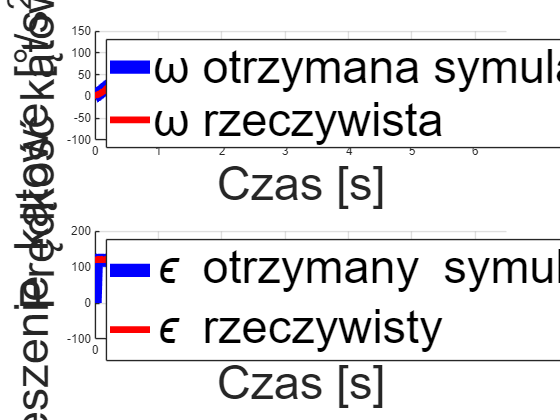

ur3_RBT = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0, 0, -9.81]);

q_home = [-0, -110, -100, -60, 90, 0]*pi/180;
q_mid1 = [90, -110, -100, -60, 90, 0]*pi/180;
q_end1 = [180, -110, -100, -60, 90, 0]*pi/180;
q_mid2 = [270, -110, -100, -60, 90, 0]*pi/180;
q_end2 = [360, -110, -100, -60, 90, 0]*pi/180;

qPoints = [q_home; q_mid1; q_end1; q_mid2; q_end2];

v_max = 0.4;
a_max = 0.8;
dt = 0.01;

q_temp = jointFullArc(qPoints, 1000);
tcp_path = zeros(size(q_temp,1), 3);

for i = 1:size(q_temp,1)
    T_i = getTransform(ur3_RBT, q_temp(i,:), 'tool0', 'base');
    tcp_path(i,:) = tform2trvec(T_i);
end

tcp_dist = sum(vecnorm(diff(tcp_path), 2, 2));

t_acc = v_max / a_max;
d_acc = 0.5 * a_max * t_acc^2;

if tcp_dist < 2*d_acc
    trajTime = 2 * sqrt(tcp_dist / a_max);
else
    trajTime = 2*t_acc + (tcp_dist - 2*d_acc)/v_max;
end

N_total = round(trajTime / dt);

qArcUniform = jointFullArc(qPoints, N_total);

s = trapezoidalScaling_noDecel(trajTime, a_max, v_max, size(qArcUniform,1));

qTraj = zeros(length(s), size(qArcUniform,2));
for j = 1:size(qArcUniform,2)
    qTraj(:,j) = interp1( linspace(0,1,size(qArcUniform,1)), qArcUniform(:,j), s, 'linear');
end

qdTraj = [zeros(1,6); diff(qTraj)/dt];
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

qdTraj(end,:) = 0;
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

T = linspace(0, trajTime, size(qTraj,1));

TCP_pos = zeros(size(qTraj,1), 3);
for i = 1:size(qTraj,1)
    T_TCP = getTransform(ur3_RBT, qTraj(i,:), 'tool0', 'base');
    TCP_pos(i,:) = tform2trvec(T_TCP);
end

TCP_vel = [zeros(1,3); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

TCP_vel(end,:) = 0;
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

max_TCP_speed = max(vecnorm(TCP_vel,2,2));

M = csvread('3712_ums.csv', 1,0);

idxB = 1; idxE = length(M);

M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
subplot(2,1,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-7.65),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 6.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;

subplot(2,1,2)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-7.65,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 6.5]); ylim([-100 200]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 765;
omega_ref = qdTraj(:,1) * 180/pi;
omega_meas = -SDLData.gZ;

omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);

omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));

fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 4.513680 [°/s]



a_ref = qddTraj(:,1) * 180/pi;
a_meas = -SDLData.aZ;

a_meas_shifted = a_meas(offset:end);

N = length(T);

a_ref = a_ref(1:N);
a_meas_shifted = a_meas_shifted(1:N);

valid_idx = (a_meas_shifted ~= 0) & (a_ref ~= 0);

a_ref_valid = a_ref(valid_idx);
a_meas_valid = a_meas_shifted(valid_idx);

if isempty(a_ref_valid)
    warning('Brak próbek spełniających warunek a_ref ≠ 0 oraz a_meas ≠ 0.');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_valid - a_meas_valid));
end

fprintf('Wartość funkcji celu I(a): %.6f [°/s^2]\n', I_acc);

Wartość funkcji celu I(a): 123.951054 [°/s^2]



I_omega_t = abs(omega_ref - omega_meas_shifted);

time_vec = T(1:N);

I_acc_t = abs(a_ref - a_meas_shifted);

I_acc_t_valid = I_acc_t;
I_acc_t_valid(~valid_idx) = NaN;

figure;
subplot(2,2,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-7.65),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 6.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,3)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-7.65,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 6.5]); ylim([-100 200]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

set(gca, 'FontSize', 35)
xlim([0 6.31]);

subplot(2,2,4)
I_acc_plot = I_acc_t_valid;
I_acc_plot(isnan(I_acc_plot)) = 0;
plot(time_vec, I_acc_plot, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
legend('Rozbieżność \epsilon', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

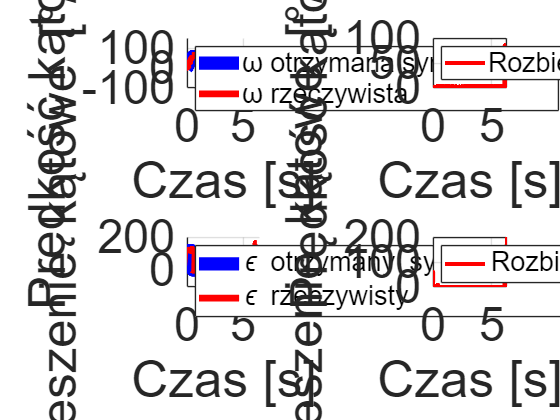

xlim([0 6.31]);
set(gca, 'FontSize', 35)

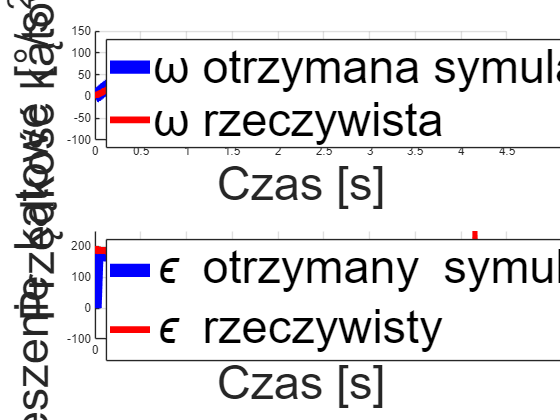

ur3_RBT = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0, 0, -9.81]);

q_home = [-0, -110, -100, -60, 90, 0]*pi/180;
q_mid1 = [90, -110, -100, -60, 90, 0]*pi/180;
q_end1 = [180, -110, -100, -60, 90, 0]*pi/180;
q_mid2 = [270, -110, -100, -60, 90, 0]*pi/180;
q_end2 = [360, -110, -100, -60, 90, 0]*pi/180;

qPoints = [q_home; q_mid1; q_end1; q_mid2; q_end2];

v_max = 0.6;
a_max = 1.2;
dt = 0.01;

q_temp = jointFullArc(qPoints, 1000);
tcp_path = zeros(size(q_temp,1), 3);

for i = 1:size(q_temp,1)
    T_i = getTransform(ur3_RBT, q_temp(i,:), 'tool0', 'base');
    tcp_path(i,:) = tform2trvec(T_i);
end

tcp_dist = sum(vecnorm(diff(tcp_path), 2, 2));

t_acc = v_max / a_max;
d_acc = 0.5 * a_max * t_acc^2;

if tcp_dist < 2*d_acc
    trajTime = 2 * sqrt(tcp_dist / a_max);
else
    trajTime = 2*t_acc + (tcp_dist - 2*d_acc)/v_max;
end

N_total = round(trajTime / dt);

qArcUniform = jointFullArc(qPoints, N_total);

s = trapezoidalScaling_noDecel(trajTime, a_max, v_max, size(qArcUniform,1));

qTraj = zeros(length(s), size(qArcUniform,2));
for j = 1:size(qArcUniform,2)
    qTraj(:,j) = interp1( linspace(0,1,size(qArcUniform,1)), qArcUniform(:,j), s, 'linear');
end

qdTraj = [zeros(1,6); diff(qTraj)/dt];
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

qdTraj(end,:) = 0;
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

T = linspace(0, trajTime, size(qTraj,1));

TCP_pos = zeros(size(qTraj,1), 3);
for i = 1:size(qTraj,1)
    T_TCP = getTransform(ur3_RBT, qTraj(i,:), 'tool0', 'base');
    TCP_pos(i,:) = tform2trvec(T_TCP);
end

TCP_vel = [zeros(1,3); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

TCP_vel(end,:) = 0;
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

max_TCP_speed = max(vecnorm(TCP_vel,2,2));

inputFile = '3721_um.csv';
outputFile = '3721_ums.csv';

data = readtable(inputFile);

M = csvread('3721_ums.csv', 1,0);

idxB = 1; idxE = length(M);

M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
subplot(2,1,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-10.57),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;

subplot(2,1,2)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-10.57,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.5]); ylim([-100 250]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 1057;
omega_ref = qdTraj(:,1) * 180/pi;
omega_meas = -SDLData.gZ;

omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);

omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));

fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 9.481223 [°/s]



a_ref = qddTraj(:,1) * 180/pi;
a_meas = -SDLData.aZ;

a_meas_shifted = a_meas(offset:end);

N = length(T);

a_ref = a_ref(1:N);
a_meas_shifted = a_meas_shifted(1:N);

valid_idx = (a_meas_shifted ~= 0) & (a_ref ~= 0);

a_ref_valid = a_ref(valid_idx);
a_meas_valid = a_meas_shifted(valid_idx);

if isempty(a_ref_valid)
    warning('Brak próbek spełniających warunek a_ref ≠ 0 oraz a_meas ≠ 0.');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_valid - a_meas_valid));
end

fprintf('Wartość funkcji celu I(a): %.6f [°/s^2]\n', I_acc);

Wartość funkcji celu I(a): 185.876050 [°/s^2]



I_omega_t = abs(omega_ref - omega_meas_shifted);

time_vec = T(1:N);

I_acc_t = abs(a_ref - a_meas_shifted);

I_acc_t_valid = I_acc_t;
I_acc_t_valid(~valid_idx) = NaN;

figure;
subplot(2,2,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-10.57),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,3)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-10.57,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.5]); ylim([-100 250]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 20);
set(gca, 'FontSize', 35)
hold off;

subplot(2,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

set(gca, 'FontSize', 35)
xlim([0 4.37]);

subplot(2,2,4)
I_acc_plot = I_acc_t_valid;
I_acc_plot(isnan(I_acc_plot)) = 0;
plot(time_vec, I_acc_plot, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
legend('Rozbieżność \epsilon', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

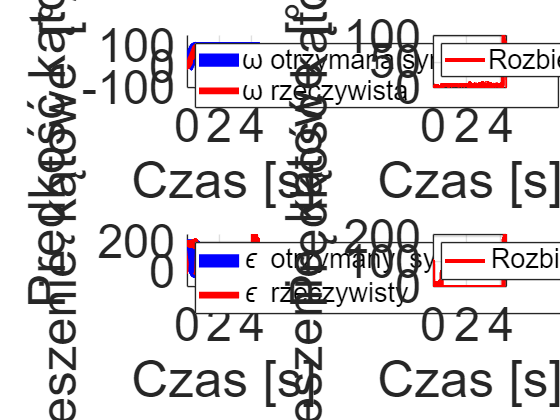

xlim([0 4.37]);
set(gca, 'FontSize', 35)

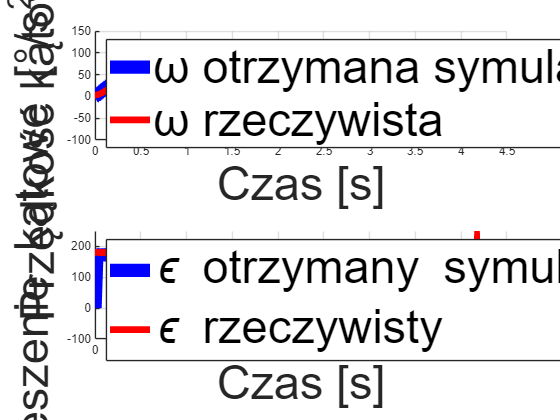

ur3_RBT = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0, 0, -9.81]);

q_home = [-0, -110, -100, -60, 90, 0]*pi/180;
q_mid1 = [90, -110, -100, -60, 90, 0]*pi/180;
q_end1 = [180, -110, -100, -60, 90, 0]*pi/180;
q_mid2 = [270, -110, -100, -60, 90, 0]*pi/180;
q_end2 = [360, -110, -100, -60, 90, 0]*pi/180;

qPoints = [q_home; q_mid1; q_end1; q_mid2; q_end2];

v_max = 0.6;
a_max = 1.2;
dt = 0.01;

q_temp = jointFullArc(qPoints, 1000);
tcp_path = zeros(size(q_temp,1), 3);

for i = 1:size(q_temp,1)
    T_i = getTransform(ur3_RBT, q_temp(i,:), 'tool0', 'base');
    tcp_path(i,:) = tform2trvec(T_i);
end

tcp_dist = sum(vecnorm(diff(tcp_path), 2, 2));

t_acc = v_max / a_max;
d_acc = 0.5 * a_max * t_acc^2;

if tcp_dist < 2*d_acc
    trajTime = 2 * sqrt(tcp_dist / a_max);
else
    trajTime = 2*t_acc + (tcp_dist - 2*d_acc)/v_max;
end

N_total = round(trajTime / dt);

qArcUniform = jointFullArc(qPoints, N_total);

s = trapezoidalScaling_noDecel(trajTime, a_max, v_max, size(qArcUniform,1));

qTraj = zeros(length(s), size(qArcUniform,2));
for j = 1:size(qArcUniform,2)
    qTraj(:,j) = interp1( linspace(0,1,size(qArcUniform,1)), qArcUniform(:,j), s, 'linear');
end

qdTraj = [zeros(1,6); diff(qTraj)/dt];
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

qdTraj(end,:) = 0;
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

T = linspace(0, trajTime, size(qTraj,1));

TCP_pos = zeros(size(qTraj,1), 3);
for i = 1:size(qTraj,1)
    T_TCP = getTransform(ur3_RBT, qTraj(i,:), 'tool0', 'base');
    TCP_pos(i,:) = tform2trvec(T_TCP);
end

TCP_vel = [zeros(1,3); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

TCP_vel(end,:) = 0;
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

max_TCP_speed = max(vecnorm(TCP_vel,2,2));

M = csvread('3722_ums.csv', 1,0);

idxB = 1; idxE = length(M);
M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
subplot(2,1,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-7.65),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;

subplot(2,1,2)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-7.65,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.5]); ylim([-100 250]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 765;
omega_ref = qdTraj(:,1) * 180/pi;
omega_meas = -SDLData.gZ;

omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);

omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));

fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 9.983958 [°/s]



a_ref = qddTraj(:,1) * 180/pi;
a_meas = -SDLData.aZ;

a_meas_shifted = a_meas(offset:end);

N = 100;

a_ref = a_ref(1:N);
a_meas_shifted = a_meas_shifted(1:N);

valid_idx = (a_meas_shifted ~= 0) & (a_ref ~= 0);

a_ref_valid = a_ref(valid_idx);
a_meas_valid = a_meas_shifted(valid_idx);

if isempty(a_ref_valid)
    warning('Brak próbek spełniających warunek a_ref ≠ 0 oraz a_meas ≠ 0.');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_valid - a_meas_valid));
end

fprintf('Wartość funkcji celu I(a): %.6f [°/s^2]\n', I_acc);

Wartość funkcji celu I(a): 9.996450 [°/s^2]



a_ref = qddTraj(:,1) * 180/pi;
a_meas = -SDLData.aZ;

a_meas_shifted = a_meas(offset:end);

N = length(T);

a_ref = a_ref(1:N);
a_meas_shifted = a_meas_shifted(1:N);

valid_idx = (a_meas_shifted ~= 0) & (a_ref ~= 0);

a_ref_valid = a_ref(valid_idx);
a_meas_valid = a_meas_shifted(valid_idx);

if isempty(a_ref_valid)
    warning('Brak próbek spełniających warunek a_ref ≠ 0 oraz a_meas ≠ 0.');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_valid - a_meas_valid));
end

I_omega_t = abs(omega_ref - omega_meas_shifted);

time_vec = T(1:N);

I_acc_t = abs(a_ref - a_meas_shifted);

I_acc_t_valid = I_acc_t;
I_acc_t_valid(~valid_idx) = NaN;

figure;
subplot(2,2,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-7.65),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);set(gca, 'FontSize', 35)
hold off;

subplot(2,2,3)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-7.65,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 4.5]); ylim([-100 250]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 20);set(gca, 'FontSize', 35)
hold off;

subplot(2,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

set(gca, 'FontSize', 35)
xlim([0 4.37]);

subplot(2,2,4)
I_acc_plot = I_acc_t_valid;
I_acc_plot(isnan(I_acc_plot)) = 0;
plot(time_vec, I_acc_plot, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
legend('Rozbieżność \epsilon', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

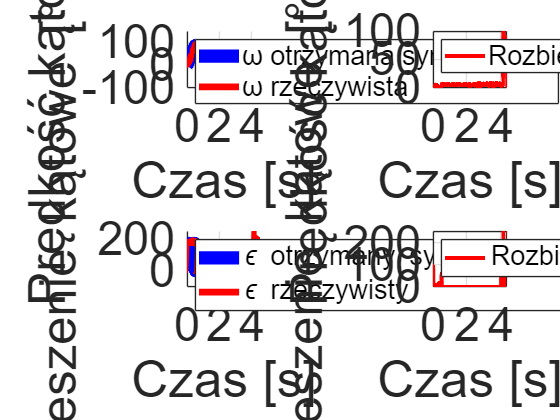

xlim([0 4.37]);
set(gca, 'FontSize', 35)

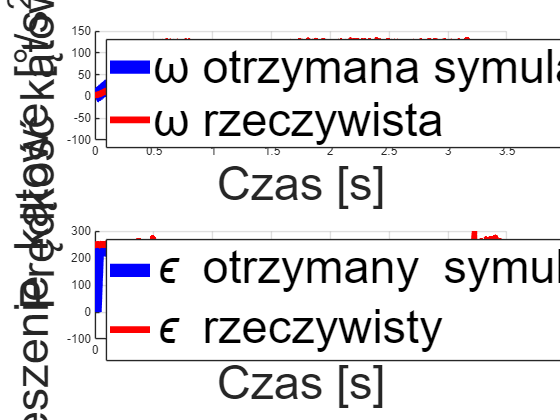

ur3_RBT = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0, 0, -9.81]);

q_home = [-0, -110, -100, -60, 90, 0]*pi/180;
q_mid1 = [90, -110, -100, -60, 90, 0]*pi/180;
q_end1 = [180, -110, -100, -60, 90, 0]*pi/180;
q_mid2 = [270, -110, -100, -60, 90, 0]*pi/180;
q_end2 = [360, -110, -100, -60, 90, 0]*pi/180;

qPoints = [q_home; q_mid1; q_end1; q_mid2; q_end2];

v_max = 0.8;
a_max = 1.6;
dt = 0.01;

q_temp = jointFullArc(qPoints, 1000);
tcp_path = zeros(size(q_temp,1), 3);

for i = 1:size(q_temp,1)
    T_i = getTransform(ur3_RBT, q_temp(i,:), 'tool0', 'base');
    tcp_path(i,:) = tform2trvec(T_i);
end

tcp_dist = sum(vecnorm(diff(tcp_path), 2, 2));

t_acc = v_max / a_max;
d_acc = 0.5 * a_max * t_acc^2;

if tcp_dist < 2*d_acc
    trajTime = 2 * sqrt(tcp_dist / a_max);
else
    trajTime = 2*t_acc + (tcp_dist - 2*d_acc)/v_max;
end

N_total = round(trajTime / dt);

qArcUniform = jointFullArc(qPoints, N_total);

s = trapezoidalScaling_noDecel(trajTime, a_max, v_max, size(qArcUniform,1));

qTraj = zeros(length(s), size(qArcUniform,2));
for j = 1:size(qArcUniform,2)
    qTraj(:,j) = interp1( linspace(0,1,size(qArcUniform,1)), qArcUniform(:,j), s, 'linear');
end

qdTraj = [zeros(1,6); diff(qTraj)/dt];
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

qdTraj(end,:) = 0;
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

T = linspace(0, trajTime, size(qTraj,1));

TCP_pos = zeros(size(qTraj,1), 3);
for i = 1:size(qTraj,1)
    T_TCP = getTransform(ur3_RBT, qTraj(i,:), 'tool0', 'base');
    TCP_pos(i,:) = tform2trvec(T_TCP);
end

TCP_vel = [zeros(1,3); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

TCP_vel(end,:) = 0;
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

max_TCP_speed = max(vecnorm(TCP_vel,2,2));

M = csvread('3731_ums.csv', 1,0);

idxB = 1; idxE = length(M);

M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
subplot(2,1,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-11.66),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;

subplot(2,1,2)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-11.66,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.5]); ylim([-100 300]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 1166;
omega_ref = qdTraj(:,1) * 180/pi;
omega_meas = -SDLData.gZ;

omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);

omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));

fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 14.225220 [°/s]



a_ref = qddTraj(:,1) * 180/pi;
a_meas = -SDLData.aZ;

a_meas_shifted = a_meas(offset:end);

N = 100;

a_ref = a_ref(1:N);
a_meas_shifted = a_meas_shifted(1:N);

valid_idx = (a_meas_shifted ~= 0) & (a_ref ~= 0);

a_ref_valid = a_ref(valid_idx);
a_meas_valid = a_meas_shifted(valid_idx);

if isempty(a_ref_valid)
    warning('Brak próbek spełniających warunek a_ref ≠ 0 oraz a_meas ≠ 0.');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_valid - a_meas_valid));
end

fprintf('Wartość funkcji celu I(a): %.6f [°/s^2]\n', I_acc);

Wartość funkcji celu I(a): 29.185150 [°/s^2]



a_ref = qddTraj(:,1) * 180/pi;
a_meas = -SDLData.aZ;

a_meas_shifted = a_meas(offset:end);

N = length(T);

a_ref = a_ref(1:N);
a_meas_shifted = a_meas_shifted(1:N);

valid_idx = (a_meas_shifted ~= 0) & (a_ref ~= 0);

a_ref_valid = a_ref(valid_idx);
a_meas_valid = a_meas_shifted(valid_idx);

if isempty(a_ref_valid)
    warning('Brak próbek spełniających warunek a_ref ≠ 0 oraz a_meas ≠ 0.');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_valid - a_meas_valid));
end

fprintf('Wartość funkcji celu I(a): %.6f [°/s^2]\n', I_acc);

Wartość funkcji celu I(a): 249.906720 [°/s^2]



I_omega_t = abs(omega_ref - omega_meas_shifted);

time_vec = T(1:N);

I_acc_t = abs(a_ref - a_meas_shifted);

I_acc_t_valid = I_acc_t;
I_acc_t_valid(~valid_idx) = NaN;

figure;
subplot(2,2,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-11.66),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);set(gca, 'FontSize', 35)
hold off;

subplot(2,2,3)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-11.66,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.5]); ylim([-100 300]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 20);set(gca, 'FontSize', 35)
hold off;

subplot(2,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

set(gca, 'FontSize', 35)
xlim([0 3.4]);

subplot(2,2,4)
I_acc_plot = I_acc_t_valid;
I_acc_plot(isnan(I_acc_plot)) = 0;
plot(time_vec, I_acc_plot, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
legend('Rozbieżność \epsilon', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

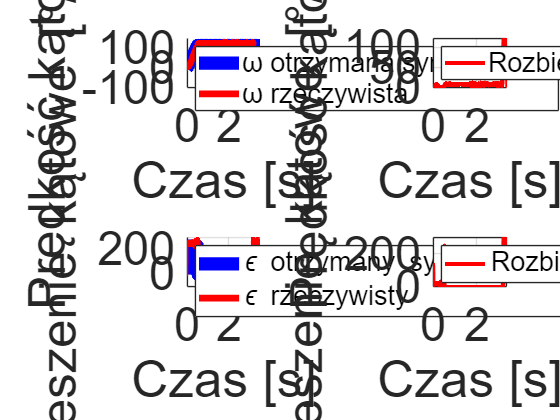

xlim([0 3.4]);
set(gca, 'FontSize', 35)

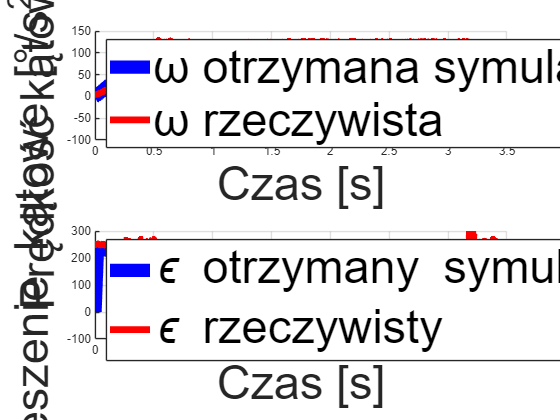

ur3_RBT = loadrobot("universalUR3", "DataFormat", "row", "Gravity", [0, 0, -9.81]);

q_home = [-0, -110, -100, -60, 90, 0]*pi/180;
q_mid1 = [90, -110, -100, -60, 90, 0]*pi/180;
q_end1 = [180, -110, -100, -60, 90, 0]*pi/180;
q_mid2 = [270, -110, -100, -60, 90, 0]*pi/180;
q_end2 = [360, -110, -100, -60, 90, 0]*pi/180;

qPoints = [q_home; q_mid1; q_end1; q_mid2; q_end2];

v_max = 0.8;
a_max = 1.6;
dt = 0.01;

q_temp = jointFullArc(qPoints, 1000);
tcp_path = zeros(size(q_temp,1), 3);

for i = 1:size(q_temp,1)
    T_i = getTransform(ur3_RBT, q_temp(i,:), 'tool0', 'base');
    tcp_path(i,:) = tform2trvec(T_i);
end

tcp_dist = sum(vecnorm(diff(tcp_path), 2, 2));

t_acc = v_max / a_max;
d_acc = 0.5 * a_max * t_acc^2;

if tcp_dist < 2*d_acc
    trajTime = 2 * sqrt(tcp_dist / a_max);
else
    trajTime = 2*t_acc + (tcp_dist - 2*d_acc)/v_max;
end

N_total = round(trajTime / dt);

qArcUniform = jointFullArc(qPoints, N_total);

s = trapezoidalScaling_noDecel(trajTime, a_max, v_max, size(qArcUniform,1));

qTraj = zeros(length(s), size(qArcUniform,2));
for j = 1:size(qArcUniform,2)
    qTraj(:,j) = interp1(linspace(0,1,size(qArcUniform,1)), qArcUniform(:,j), s, 'linear');
end

qdTraj = [zeros(1,6); diff(qTraj)/dt];
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

qdTraj(end,:) = 0;
qddTraj = [zeros(1,6); diff(qdTraj)/dt];

T = linspace(0, trajTime, size(qTraj,1));

TCP_pos = zeros(size(qTraj,1), 3);
for i = 1:size(qTraj,1)
    T_TCP = getTransform(ur3_RBT, qTraj(i,:), 'tool0', 'base');
    TCP_pos(i,:) = tform2trvec(T_TCP);
end

TCP_vel = [zeros(1,3); diff(TCP_pos)/dt];
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

TCP_vel(end,:) = 0;
TCP_acc = [zeros(1,3); diff(TCP_vel)/dt];

max_TCP_speed = max(vecnorm(TCP_vel,2,2));

M = csvread('3732_ums.csv', 1,0);

idxB = 1; idxE = length(M);

M = M(idxB:idxE, :);

VarNames = {'Id','SessionId','aX','aY','aZ','gX','gY','gZ','mX','mY','mZ','Thermometer','Barometer','Trigger'};
SDLData = cell2struct(num2cell(M, 1), VarNames,2);

figure;
subplot(2,1,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-7.18),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 35);
hold off;

subplot(2,1,2)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-7.18,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.5]); ylim([-100 300]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 35);
hold off;


offset = 718;
omega_ref = qdTraj(:,1) * 180/pi;
omega_meas = -SDLData.gZ;

omega_meas_shifted = omega_meas(offset+1:end);

N_ref = length(omega_ref);
N_meas = length(omega_meas_shifted);
N = min(N_ref, N_meas);

omega_ref = omega_ref(1:N);
omega_meas_shifted = omega_meas_shifted(1:N);

I_omega = mean(abs(omega_ref - omega_meas_shifted));

fprintf('Wartość funkcji celu I(ω): %.6f [°/s]\n', I_omega);

Wartość funkcji celu I(ω): 15.175090 [°/s]



a_ref = qddTraj(:,1) * 180/pi;
a_meas = -SDLData.aZ;

a_meas_shifted = a_meas(offset:end);

N = length(T);

a_ref = a_ref(1:N);
a_meas_shifted = a_meas_shifted(1:N);

valid_idx = (a_meas_shifted ~= 0) & (a_ref ~= 0);

a_ref_valid = a_ref(valid_idx);
a_meas_valid = a_meas_shifted(valid_idx);

if isempty(a_ref_valid)
    warning('Brak próbek spełniających warunek a_ref ≠ 0 oraz a_meas ≠ 0.');
    I_acc = NaN;
else
    I_acc = mean(abs(a_ref_valid - a_meas_valid));
end

fprintf('Wartość funkcji celu I(a): %.6f [°/s^2]\n', I_acc);

Wartość funkcji celu I(a): 251.978212 [°/s^2]



I_omega_t = abs(omega_ref - omega_meas_shifted);

time_vec = T(1:N);

I_acc_t = abs(a_ref - a_meas_shifted);

I_acc_t_valid = I_acc_t;
I_acc_t_valid(~valid_idx) = NaN;

figure;
subplot(2,2,1)
hold on;
plot(T, qdTraj(:,1)*180/pi, 'b', 'LineWidth', 10);
plot((SDLData.Id/100-7.18),  -SDLData.gZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.5]); ylim([-100 150]);
legend('ω otrzymana symulacyjnie', 'ω rzeczywista','Location', 'Southwest', 'FontSize', 20);set(gca, 'FontSize', 35)
hold off;

subplot(2,2,3)
hold on;
plot(T, (qddTraj(:,1))*180/pi, 'b', 'LineWidth', 10);
plot(SDLData.Id/100-7.18,  -SDLData.aZ, 'Color', [1 0 0], 'LineWidth', 5);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
xlabel('Czas [s]', 'FontSize', 35);
grid on;xlim([0 3.5]); ylim([-100 300]);
legend('\epsilon otrzymany symulacyjnie', '\epsilon rzeczywisty','Location', 'Southwest', 'FontSize', 20);set(gca, 'FontSize', 35)
hold off;

subplot(2,2,2)
plot(time_vec, I_omega_t, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 30);
ylabel('Prędkość kątowa [°/s]', 'FontSize', 35); 
legend('Rozbieżność ω', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

set(gca, 'FontSize', 35)
xlim([0 3.4]);

subplot(2,2,4)
I_acc_plot = I_acc_t_valid;
I_acc_plot(isnan(I_acc_plot)) = 0;
plot(time_vec, I_acc_plot, 'r', 'LineWidth', 3);
grid on;
xlabel('Czas [s]', 'FontSize', 35);
ylabel('Przyspieszenie kątowe [°/s^2]', 'FontSize', 35); 
legend('Rozbieżność \epsilon', 'ω rzeczywista','Location', 'Northwest', 'FontSize', 20);

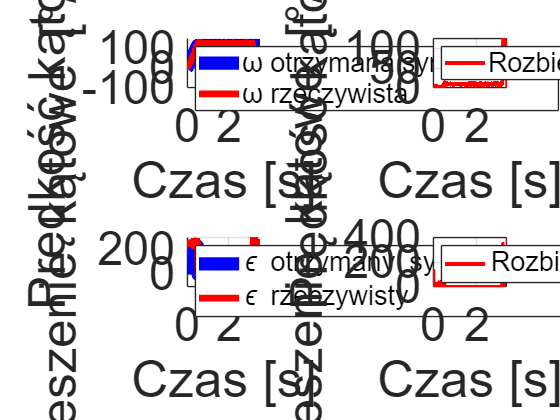

xlim([0 3.4]);
set(gca, 'FontSize', 35)


%% === FUNKCJE ===

function qArc = jointFullArc(qPoints, N)
    M = size(qPoints, 1);
    totalDist = 0;
    segLen = zeros(M-1,1);

    for i = 1:M-1
        segLen(i) = norm(qPoints(i+1,:) - qPoints(i,:));
        totalDist = totalDist + segLen(i);
    end

    qArc = [];
    for i = 1:M-1
        Ni = round(N * segLen(i) / totalDist);
        qPart = jointLinearInterp(qPoints(i,:), qPoints(i+1,:), Ni+1);
        if i > 1
            qPart = qPart(2:end,:);
        end
        qArc = [qArc; qPart];
    end
end

function qLin = jointLinearInterp(q1, q2, N)
    qLin = zeros(N, length(q1));
    for i = 1:length(q1)
        qLin(:,i) = linspace(q1(i), q2(i), N)';
    end
end

function s = trapezoidalScaling_noDecel(trajTime, a_max, v_max, N)

    dt = trajTime / (N - 1);
    t = linspace(0, trajTime, N);

    t_acc = v_max / a_max;
    d_acc = 0.5 * a_max * t_acc^2;

    if t_acc > trajTime
        t_acc = trajTime; 
    end

    s_raw = zeros(size(t));
    for i = 1:length(t)
        if t(i) <= t_acc
            s_raw(i) = 0.5 * a_max * t(i)^2;
        else

            s_raw(i) = d_acc + v_max * (t(i) - t_acc);
        end
    end

    s = s_raw / max(s_raw);
end






